%Celal AKSOY

# Modelling, Analysis and Control of the Systems in State Space Form

## Suspension System

## 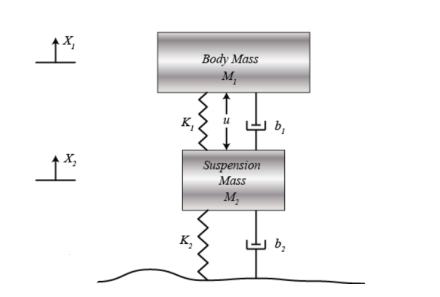

#### Parameters

m1 = 2500;        % Mass 1                      [kg]
m2 = 320;         % Mass 2                      [kg]
k1 = 80000;       % Spring Constant 1           [N/m] 
k2 = 500000;      % Spring Constant 2           [N/m]
b1 = 350;         % Viscous Friction Constant 1 [Ns/m]
b2 = 15020;       % Viscous Friction Constant 2 [Ns/m]

#### Transfer Function   

To compare with what we get with state space

s = tf('s');
G1 = ((m1+m2)*s^2+b2*s+k2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1))  

G1 =
 
                  2820 s^2 + 15020 s + 500000
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



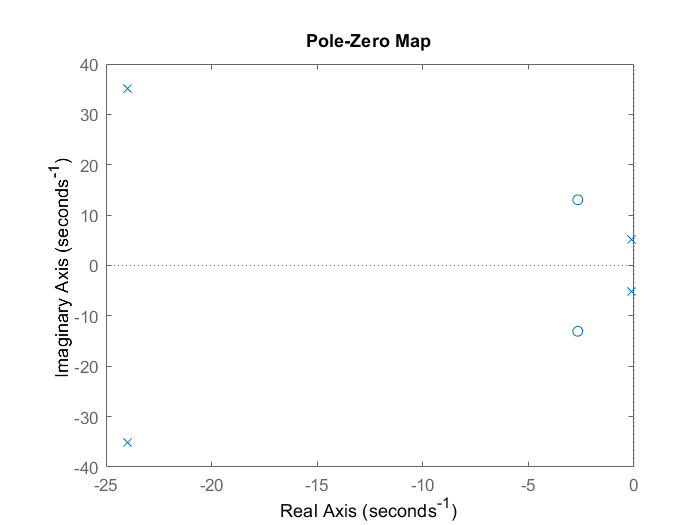

pzmap(G1)

The system is a 4th order system. All 4 roots are in the left half plane. So system is stable.

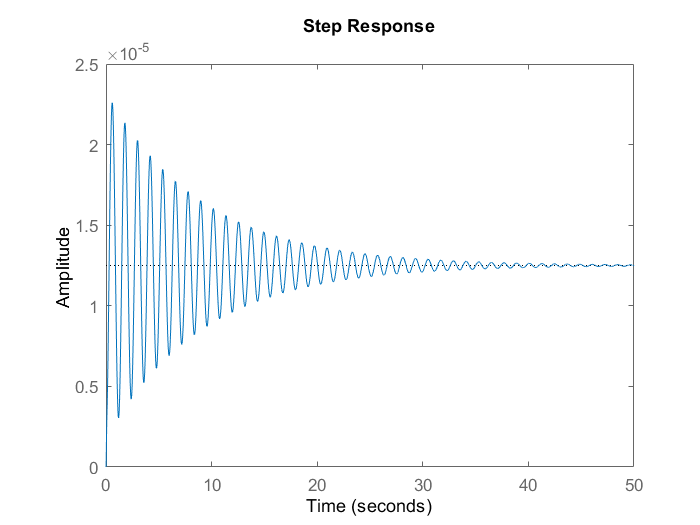

step(G1)

#### X1_dot, X1_dotdot, X2_dot, X2_dotdot as System State (Experimental)

In this section, I took the first and second derivatives of X1 and X2 as state

% System Matrix
Aex = [1 0 0 0 ; -b1/m1, -k1/m1, b1/m1, k1/m1 ; 0 0 1 0 ; b1/m2, k1/m2, -(b1+b2)/m2, -(k1+k2)/m2]; 
Bex = [0 ; 1/m1 ; 0 ; -1/m2]; % Input Matrix
Cex = [0 1 0 -1]; % Output matrix

We usually take the D matrix as zero because we don't want the input to affect the output directly.

Dex = [0]; % Feedthrough Matrix
experimental = ss(Aex,Bex,Cex,Dex)

experimental =
 
  A = 
           x1      x2      x3      x4
   x1       1       0       0       0
   x2   -0.14     -32    0.14      32
   x3       0       0       1       0
   x4   1.094     250  -48.03   -1813
 
  B = 
              u1
   x1          0
   x2     0.0004
   x3          0
   x4  -0.003125
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0  -1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



#### From State Space to Transfer Function

Actually, I did not realize the function that converts state space into a transfer function, so I derived a transfer function from the formula taught in the lesson.

Gex = zpk(Cex*inv(eye(4)*s-Aex)*Bex+Dex)

Gex =
 
  0.003525 (s+1817)^3 (s+177.3) (s+27.52)^3
  -----------------------------------------
           (s+1817)^4 (s+27.52)^4
 
Continuous-time zero/pole/gain model.



[num3,den3] = ss2tf(Aex,Bex,Cex,Dex); % Alternative formula
Gex2 = tf(num3,den3)

Gex2 =
 
    0.003525 s^3 + 0.6179 s^2 - 1.246 s + 0.625
  -----------------------------------------------
  s^4 + 1843 s^3 + 46312 s^2 - 9.816e04 s + 50000
 
Continuous-time transfer function.



I check whether I can reach the transfer function with the state space I obtained.

Gex1 = Cex*inv(eye(4)*s-Aex)*Bex+Dex;
if isequal(Gex1,G1)
    disp('State space representation is successfull.');
else
    disp('State space representation is unsuccessfull.');
end

State space representation is unsuccessfull.


#### Roots of Characteristic Equation

The roots of our characteristic equation are also equal to the eigenvalue of the matrix Aex.

syms lambdaex
Rootex = vpasolve(det(eye(4)*lambdaex - Aex)==0,lambdaex) 

$$Rootex = \left(\begin{array}{c} -1816.981838318051583573380782157\\ -27.518161681948416426619217842975\\ 1.0\\ 1.0 \end{array}\right)$$

There are 2 positive roots. So the system is unstable

eig(Aex) %for control purposes

ans = 	1.0e+03 *

   -1.8170
   -0.0275
    0.0010
    0.0010


#### Controllability

Controlex = [Bex Aex*Bex Aex^2*Bex Aex^3*Bex] 

Controlex = 	1.0e+07 *

         0         0         0         0
    0.0000   -0.0000    0.0000   -0.0341
         0         0         0         0
   -0.0000    0.0000   -0.0010    1.9034


det(Controlex)

ans = 0

The determinant being zero means it cannot be controlled.

rank(Controlex)

ans = 2

We see that although it is a 4th order system, the system has only 2 linearly independent equations. This is why the system is uncontrollable.

#### Observability

Observex = [Cex;Cex*Aex;Cex*Aex^2;Cex*Aex^3] 

Observex = 	1.0e+09 *

         0    0.0000         0   -0.0000
   -0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0005   -0.0001   -0.0034
   -0.0037   -0.8531    0.1610    6.0909


det(Observex)

ans = 0.0061

Determinant is very close to zero. Acceptable as zero.

rank(Observex)

ans = 3

Not even full rank

#### Pole-Zero Map

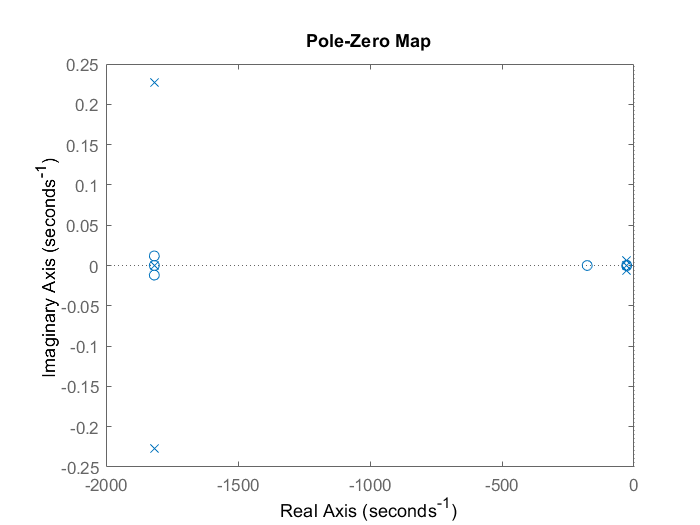

pzmap(Gex)

There are pole-zero cancellations. This equation explains the linear dependence of our system.

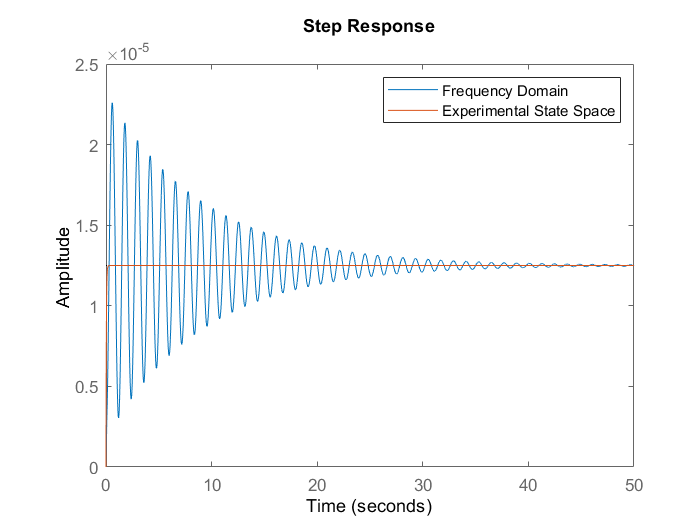

figure
step(G1)
hold on
step(Gex1)
legend('Frequency Domain','Experimental State Space')
hold off

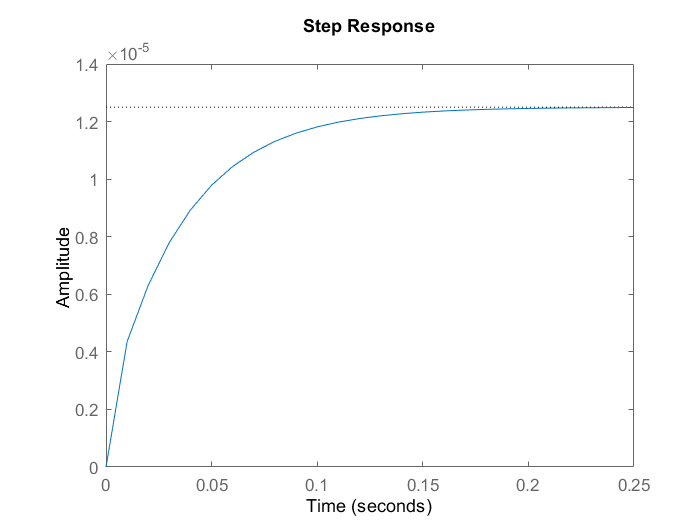

step(Gex1)

Ultimately, the final value of the system is correct, but this unfortunately does not help us understand the system. To explain, the system is actually a 4th order system, but when we apply a step input, we get a 2nd order overdamped system response. So this means that as we saw above, our states are linearly dependent. So we need to change the state set.

#### First and Second Derivatives of X and Y as System State

A = [0 0 1 0 ; (b2/m2), -((b1/m1) + (b1+b2)/m2), 0, 1 ; -(b1*b2)/(m1*m2), ((b1/m1)*((b1/m1)+(b1+b2)/m2)-(k1/m1)), 0, (-b1/m1) ; (k2/m2), -(k1/m1 +(k1+k2)/m2), 0 0];
B = [0;0;1/m1;(1/m1)+(1/m2)];
C = [0 1 0 0];
D = [0];
suspensionss = ss(A,B,C,D)

suspensionss =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2   46.94  -48.17       0       1
   x3  -6.571  -25.26       0   -0.14
   x4    1563   -1845       0       0
 
  B = 
             u1
   x1         0
   x2         0
   x3    0.0004
   x4  0.003525
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



#### From State Space to Transfer Function

Gsuspansion = zpk(C*inv(s*eye(4)-A)*B+D)

Gsuspansion =
 
  0.003525 (s^2 + 0.2197s + 27.58) (s^2 + 5.326s + 177.3) (s^2 + 47.95s + 1813)
  -----------------------------------------------------------------------------
                (s^2 + 0.2197s + 27.58)^2 (s^2 + 47.95s + 1813)^2
 
Continuous-time zero/pole/gain model.



[num4,den4] = ss2tf(A,B,C,D); % Alternative formula
Gsus = tf(num4,den4)

Gsus =
 
       0.003525 s^2 + 0.01878 s + 0.625
  ------------------------------------------
  s^4 + 48.17 s^3 + 1851 s^2 + 1721 s + 5e04
 
Continuous-time transfer function.



I check whether I can reach the transfer function with the state space I obtained.

f = @(s) C*inv(eye(4)*s-A)*B+D;
f1 = @(s) ((m1+m2)*s^2+b2*s+k2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1));

if f(0)==f1(0)
    disp('State space representation is successfull.');
else
    disp('State space representation is unsuccessfull.');
end

State space representation is successfull.


#### Roots of Characteristic Equation

The roots of our characteristic equation are also equal to the eigenvalue of the matrix A.

syms lambda1
Rootsus = vpasolve(det(eye(4)*lambda1 - A)==0,lambda1)

$$Rootsus = \left(\begin{array}{c} -23.975781785998931285143580463412-35.18692353072160658183939512864\,\mathrm{i}\\ -23.975781785998931285143580463412+35.18692353072160658183939512864\,\mathrm{i}\\ -0.10984321400106871485641953658844+5.2504454042871730157422342276366\,\mathrm{i}\\ -0.10984321400106871485641953658844-5.2504454042871730157422342276366\,\mathrm{i} \end{array}\right)$$

There are 4 negative roots. So the system is stable

eig(A) %for control purposes

ans =  -23.9758 +35.1869i
 -23.9758 -35.1869i
  -0.1098 + 5.2504i
  -0.1098 - 5.2504i


#### Controllability

Controlsuspansion = [B A*B A^2*B A^3*B] 

Controlsuspansion =          0    0.0004   -0.0005   -0.0917
         0    0.0035   -0.1510    1.3752
    0.0004   -0.0005   -0.0917    4.6404
    0.0035         0   -5.8769  277.8013


det(Controlsuspansion)

ans = -3.8147e-06

The system can be controlled.

rank(Controlsuspansion)

ans = 4

Being full rank also proves its controllability.

#### Observability

Observesuspansion = [C;C*A;C*A^2;C*A^3] 

Observesuspansion = 	1.0e+04 *

         0    0.0001         0         0
    0.0047   -0.0048         0    0.0001
   -0.0699    0.0476    0.0047   -0.0048
   -5.3235    6.4738   -0.0699    0.0469


det(Observesuspansion)

ans = -2.4414e+06

The determinant is nonzero. So the system can be observed.

rank(Observesuspansion)

ans = 4

Being full rank also proves its observability.

pzmap(Gsus)

We obtained the same result with the pole-zero map of the transfer function we obtained with the frequency domain. So our state space realization is successful

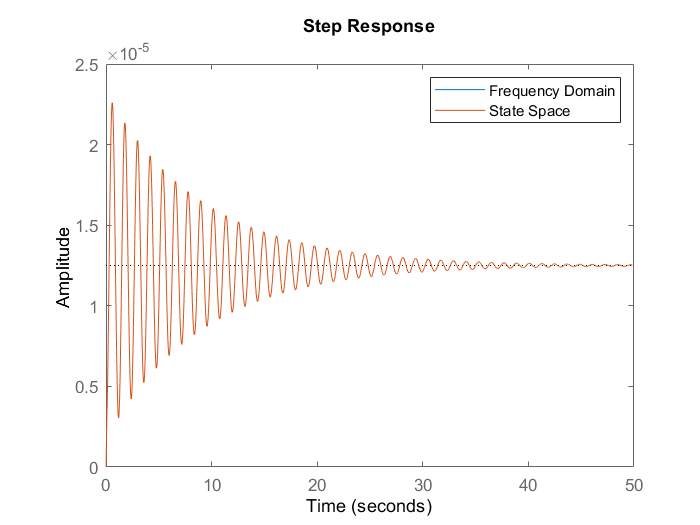

figure
step(G1)
hold on
step(Gsuspansion)
legend('Frequency Domain','State Space')
hold off

Our state-space realization is successfully completed

## Ball and Beam System

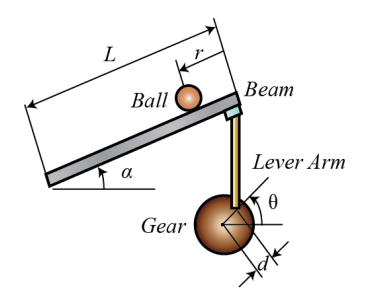

#### Parameters

clear all

J = 9.99*10^-6;         % Moment of inertia of the ball   [kg/m^2]
m = 0.11;               % Mass of the ball                [kg]
R = 0.015;              % Radius of the ball              [m]
d = 0.03;               % Lever arm offset                [m]
g = -9.8;               % Gravitational acceleration      [m/s^2]
L = 1;                  % Length of the beam              [m]

#### Transfer Function   

To compare with what we get with state space

s = tf('s');
G2 = -((m*g*d)/(L*((J/R^2)+m)))*(1/s^2)

G2 =
 
  0.2095
  ------
   s^2
 
Continuous-time transfer function.



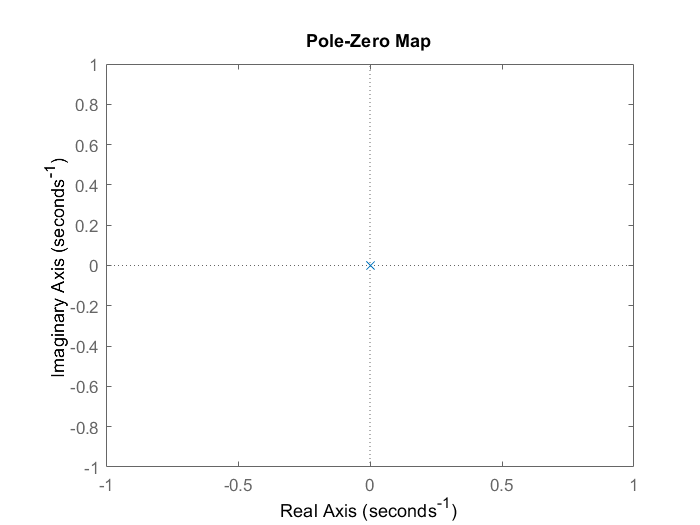

pzmap(G2)

We have 2 roots at the origin, we probably have an unstable system. 

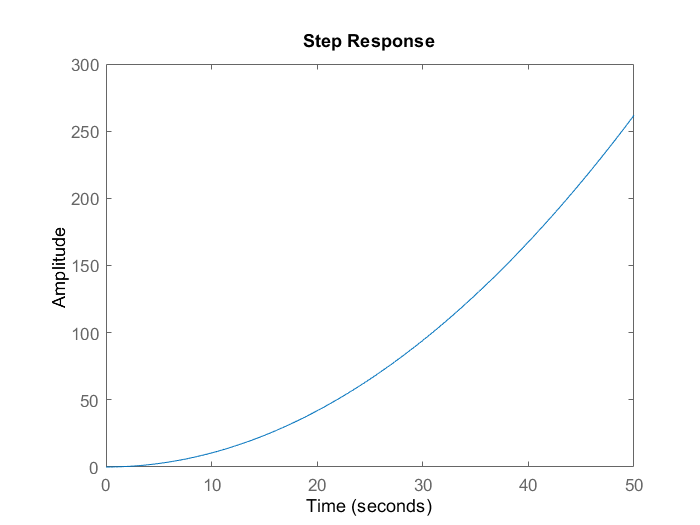

step(G2)

As can be seen from the graph, we have a diverging system. We can understand this from the fact that the ball rolls and leaves the system.

#### First and Second Derivative of r as System State

A = [0 1; 0 0];                            % System Matrix 
B = [0 ; -(m*g*d)/(L*m + (L*J/(R^2)))];    % Input Matrix
C = [1 0];                                 % Output Matrix

We usually take the D matrix as zero because we don't want the input to affect the output directly.

D = [0];                                   % Feedthrough Matrix

ballbeamss = ss(A,B,C,D)

ballbeamss =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
           u1
   x1       0
   x2  0.2095
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



#### From State Space to Transfer Function

Gballbeam = zpk(C*inv(eye(2)*s-A)*B+D)

Gballbeam =
 
  0.20946
  -------
    s^2
 
Continuous-time zero/pole/gain model.



[num5,den5] = ss2tf(A,B,C,D); % Alternative formula
Gball = tf(num5,den5)

Gball =
 
  0.2095
  ------
   s^2
 
Continuous-time transfer function.



#### Roots of Characteristic Equation

The roots of our characteristic equation are also equal to the eigenvalue of the matrix A.

syms lambda2
Rootsus = vpasolve(det(eye(2)*lambda2 - A)==0,lambda2)

$$Rootsus = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

The system has 2 roots at the origin. The system is not stable

eig(A) % for control purpose

ans =      0
     0


#### Controllability

Controlballbeam = [B A*B] 

Controlballbeam =          0    0.2095
    0.2095         0


det(Controlballbeam)

ans = -0.0439

The system can be controlled

rank(Controlballbeam)

ans = 2

Also system full rank. 

#### Observability

Observeballbeam = [C;C*A] 

Observeballbeam =      1     0
     0     1


det(Observeballbeam)

ans = 1

The determinant is nonzero. So the system can be observed.

rank(Observeballbeam)

ans = 2

Being full rank also proves its observability.

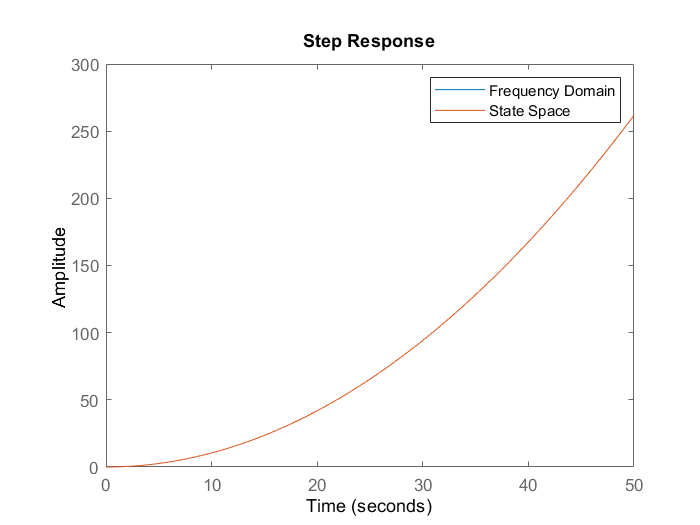

figure
step(G2)
hold on
step(ballbeamss)
hold off
legend('Frequency Domain','State Space')

As can be seen from the graph, our state space realization was successful because they overlap

#### Design a Feedback Controller

The first step in controller design is to see if our state space realization can be controlled. But we already know that our system is controllable.

syms a1 a2 s kbar1 kbar2

Overshoot = 0.05; %Desired Overshoot= %5
Zeta = -log(Overshoot)/sqrt(pi^2+log(Overshoot)^2)

Zeta = 0.6901

SettlingTime = 2; %Desired Settling Time= 2 second
Sigma = 4 /SettlingTime;
wn = Sigma/Zeta

wn = 2.8981

Pd =s^2+2*Zeta*wn*s+wn^2 %Desired Polynomial

$$Pd = s^{2}+4\,s+\frac{147756731097669}{17592186044416}$$

Roots of our desired polynomial for comparison purposes.

RootPd = vpasolve(Pd==0,s)

$$RootPd = \left(\begin{array}{c} -2.0-2.0973787820249770450048375852454\,\mathrm{i}\\ -2.0+2.0973787820249770450048375852454\,\mathrm{i} \end{array}\right)$$

Our system contains 2 negative complex roots. So the system is stable

%To generate matrix in CCF form from our desired characteristic equation
d = coeffs(Pd,s,'all');
x1 = -d(3)

$$x1 = -\frac{147756731097669}{17592186044416}$$

x2 = -d(2)

$$x2 = -4$$

Our system matrices with coordinate transform applied. We must find a1 and a2 values.

Abar1 = [0 1; -a2 -a1];
Bbar = [0 ; 1];

Even if the states are different, the transfer function remains the same. Based on this information, if we equalize the eigenvalues of the desired matrix and our system matrix, we can reach the values of a1 and a2 from this equation.

Cd = det(eye(2)*s-Abar1) % desired equation

$$Cd = s^{2}+a_{1}\,s+a_{2}$$

Cp = det(eye(2)*s-A) % characteristic equation

$$Cp = s^{2}$$

Cdcoeff = coeffs(Cd,s,'all');
Cpcoeff = coeffs(Cp,s,'all');
problem = Cdcoeff==Cpcoeff;
solution = solve(problem);
a1 = double(solution.a1)

a1 = 0

a2 = double(solution.a2)

a2 = 0

Abar1 % Coordinate transformed A matrix

$$Abar1 = \left(\begin{array}{cc} 0 & 1\\ -a_{2} & -a_{1} \end{array}\right)$$

Abar = [0 1; -a2 -a1];
T = [Bbar Abar*Bbar]*inv(Controlballbeam) % Transformer Matrix

T =     4.7743         0
         0    4.7743


If we equate our transformed matrix to our desired matrix, we get the transformed k values.

Abar-Bbar*[kbar1 kbar2];
problem2 = Abar-Bbar*[kbar1 kbar2] == [0 1 ; x1 x2]

$$problem2 = \left(\begin{array}{cc} 0=0 & 1=1\\ -{\mathrm{kbar}}_{1}=-\frac{147756731097669}{17592186044416} & -{\mathrm{kbar}}_{2}=-4 \end{array}\right)$$

solution = solve(problem2);
kbar1 = double(solution.kbar1);
kbar2 = double(solution.kbar2);
Kbar = [kbar1 kbar2]

Kbar =     8.3990    4.0000


If we convert it to the real k value

K = Kbar*T % Our Controller Values

K =    40.0991   19.0971


If we put this in place and check.

G3 = det(eye(2)*s-A+B*K)

$$G3 = s^{2}+4\,s+\frac{147756731097669}{17592186044416}$$

Rootball = vpasolve(G3==0,s)

$$Rootball = \left(\begin{array}{c} -2.0-2.0973787820249770450048375852454\,\mathrm{i}\\ -2.0+2.0973787820249770450048375852454\,\mathrm{i} \end{array}\right)$$

if isequal(G3,Pd)
    disp('Controller design is successfull')
else
    disp('Controller design is unsuccessfull')
end

Controller design is successfull


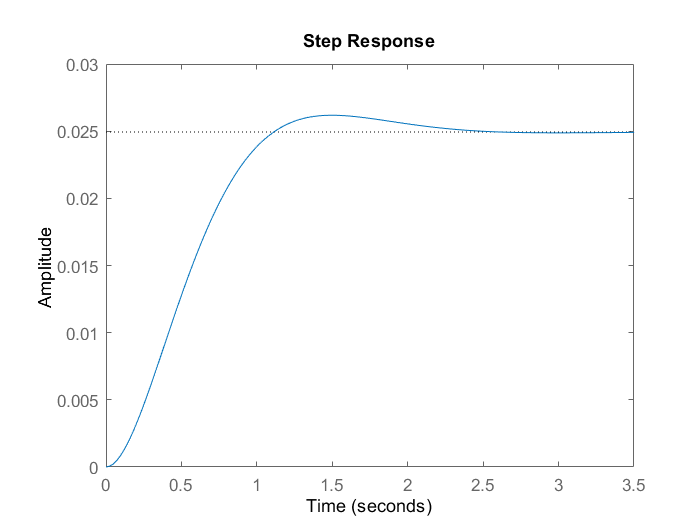

figure
[num den]=ss2tf(A-B*K,B,C,D);
G2cl = tf(num,den);
step(G2cl)

stepinfo(G2cl)

ans = struct with fields:
        RiseTime: 0.7236
    SettlingTime: 2.0687
     SettlingMin: 0.0225
     SettlingMax: 0.0262
       Overshoot: 5.0000
      Undershoot: 0
            Peak: 0.0262
        PeakTime: 1.4967


As seen in the figure, the controller we applied stabilized the system. However, the Settling Time requirement could not be met. This is because the general equations we apply to find zeta and wn are different from the algorithm MATLAB uses to find zeta and wn, and the equations we use give accurate results only under certain conditions.